# lora sim script

## lora parameters

%clear;
SF=12; %spreading factor 7-12
Fs=125e3;%samplingrate = BW
SPS=2^SF;%samples per symbol



## sim parameters

%data
%numSym=round(50000/SF);
numSym=840;

randomData=false;
%channel
perfectChannel=true;%no  awgn
maxDopplerShift=0%0.45*Fs/(2^SF);%shift has to be less than 0.5*Fs/(2^SF) to have no impact

maxDopplerShift = 0

flatDoppler=false;%true: apply same shift to entire signal, false: gradient from +maxShift to -maxShift over length of signal
maxSNR=5; %signal to noise ratio in dB
%loops
nLoops=1;
loopSNR=false;
SNRstepsize=2;
loopDoppler=false;
dopplerRate=257;
dopplerStepsize=dopplerRate/Fs;%dopplerrate*sampletime

plotSpectrogram=true;

## tx

%generate data
dataLength=numSym*SF;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    symbol=0;%generate symbols with certain value
    messageBits=transpose(repmat(dec2bin(symbol,SF)-'0',1,numSym));% -'0' to convert binary string to vector
end
%generate lora signal
[loraSignal,decimalSymbols]=generateLoraSignal(messageBits,SF,numSym);
decimalSymbols

decimalSymbols =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


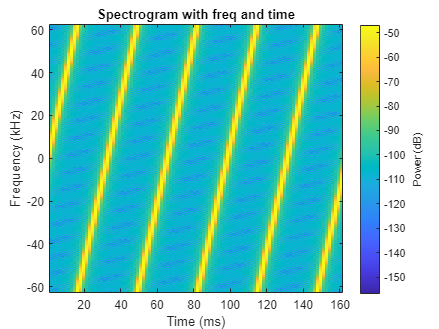

if plotSpectrogram
    %spectroram of first 5 symbols
    figure
    windowLength=round((SPS)/10);
    spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
    title('Spectrogram with freq and time')
    % figure
    % spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
    % title('Spectrogram with freq index and samples')
end

## channel & rx

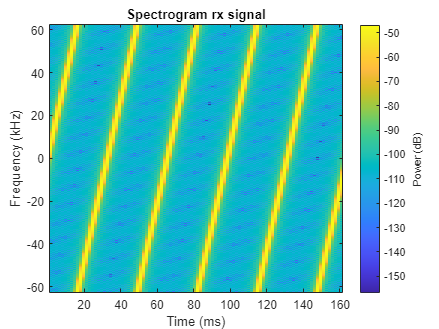

     0     1     1     2     2     3     4     4     5     5     6     6     7     7     8     9     9    10    10    11    11    12    12    13    14    14    15    15    16    16    17    17    18    18    19    20    20    21    21    22    22    23    23    24    25    25    26    26    27    27    28    28    29    30    30    31    31    32    32    33    33    34    34    35    36    36    37    37    38    38    39    39    40    41    41    42    42    43    43    44    44    45    46    46    47    47    48    48    49    49    50    50    51    52    52    53    53    54    54    55    55    56    57    57    58    58    59    59    60    60    61    62    62    63    63    64    64    65    65    66    67    67    68    68    69    69    70    70    71    71    72    73    73    74    74    75    75    76    76    77    78    78    79    79    80    80    81    81    82    83    83    84    84    85    85    86    86    87    87    88    89    89    90    90    91    91    

%channel
for counter=1:nLoops


    symbolDuration=(2^SF)/Fs;

    t=(symbolDuration/2^SF:symbolDuration/2^SF:symbolDuration*numSym);
    
    if flatDoppler
        freqShift=maxDopplerShift;
        dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
    else%apply dopper rate
        freqShift=zeros(1,length(t));
        
        for i=1:length(t)
            freqShift(i)=maxDopplerShift+dopplerRate*t(i);
        end
        %freqShift=linspace(dopplerShift,-dopplerShift,length(t));
        dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
    end
    
    if perfectChannel% use maxDopplerShift = 0 for truly perfect channel
        rxSignal = loraSignal.* (dopplerEffect);
    
    else
        if loopSNR
            rxSignal=(awgn(loraSignal,maxSNR-(counter-1)*SNRstepsize,'measured'));
        else
            rxSignal=(awgn(loraSignal,maxSNR,'measured'));
        end
        %snr
    end

    if (plotSpectrogram && counter==nLoops)
        %spectroram of first 5 symbols
        figure
        windowLength=round((SPS)/10);
        spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
        title('Spectrogram rx signal')
        % figure
        % spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
        % title('Spectrogram with freq index and samples')
    end

    %rx
    [decodedBits,decodedSymbols]=demodulateLoraSignal(rxSignal,SF,numSym);
    if counter==nLoops
        disp(decodedSymbols)
    end
    errors(counter)=sum(messageBits~=decodedBits);
end

## ber

'Adaptive Parameters for LoRa-Based Networks Physical-Layer' for ber formula

%lora_ber=errors/dataLength
lora_ser=sum(transpose(decimalSymbols~=decodedSymbols))/numSym

lora_ser = 0.9988

lora_ber7=errors/dataLength

lora_ber7 = 0.3596

% lora_ber10=errors/dataLength
% lora_ber12=errors/dataLength

if loopSNR
    figure
    
    SNRvec=flip((maxSNR-(nLoops-1)*SNRstepsize):SNRstepsize:maxSNR);
    theoryBer12=qfunc((log(12)/log(12))/sqrt(2)*(SNRvec+10*log10((2^12)/12)));
    
    theoryBer7=-0.5+qfunc((log(7)/log(12))/sqrt(2)*(SNRvec+10*log10((2^7)/7)));
    % semilogy(SNRvec',theoryBer12,'-*')
    % hold on
    % semilogy(SNRvec',theoryBer7,'-*')
    %hold on
    semilogy(SNRvec',lora_ber7,'-*')
    hold on
    %semilogy(SNRvec',lora_ber10,'-*')
    semilogy(SNRvec',lora_ber12,'-*')
    semilogy(SNRvec',nbiot_ber,'-*')
    grid on
    xlabel('SNR (dB)')
    ylabel('Bit Error Rate')
    ylim([10e-4 1])
    %legend('theory 12','theory 7','SF 7','SF 9','SF 12')%adjust legend!
    legend( 'SF 7','SF 12','NB-IoT')
    title('BER vs SNR of LoRa and NB-IoT signals')
    
end

%% compare with nbiot


## doppler corection

shifting the signal with n kHz will shift the demodulated symbol with (dopplerShift/BW)*SF

e.g. with SF=7, symbol 0 will be demodulated as 66 when the signal is shifted with 64 kHz 

original symbol = received symbol -(dopplerShift/125kHz)*SF)

to estimate frequency shift: ((receivedSymbol-expectedSymbol)/SF)*BW